**Graphics: 2D Transformations**

**2D Transformations of a Square**

In this mini project, I explored 2D geometric transformations by applying scaling, rotation, and translation to a square and visualizing the results. This exercise demonstrated how transformation matrices can be combined to achieve complex effects, helping me better understand the mechanics of geometric transformations. I began by defining a square's coordinates, representing its vertices as a matrix. The square served as the baseline for observing transformations. To enhance the visualization, I created a dedicated figure with clear axis limits and gridlines, ensuring that the transformations would be easy to follow.

**Creating and Combining Transformations**

To transform the square, I adjusted the square's dimensions by defining scaling factors along the x and y axes. This transformation either stretched or compressed the square. Then I rotated the square by 45 degrees using a rotation matrix, introducing a noticeable angular shift. And then I shifted the square's position in the x-y plane by applying a translation matrix.

By combining these transformations into a single matrix, I created a composite effect that scaled, rotated, and translated the square in one operation.

This project provided a hands-on understanding of how transformation matrices work and how they can be combined for more complex effects. Visualizing these transformations made the mathematical concepts behind scaling, rotation, and translation more tangible.

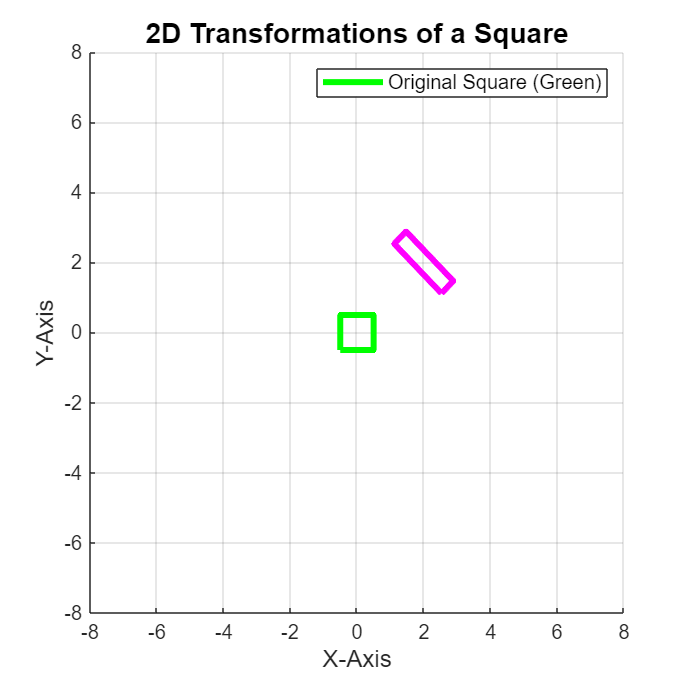

% Open figure and create axis
% I am opening a figure and setting its properties.
Figureh = figure('NumberTitle', 'off', 'Name', 'Transformation Example', ...
    'Position', [200, 200, 700, 700]); % The background is red to highlight the axes area.
Axesh = axes('XLim', [-8 8], 'YLim', [-8, 8]);

% Initializing Variables
% I defined the coordinates of a square and parameters for transformations.
square = [-0.5, -0.5; -0.5, 0.5; 0.5, 0.5; 0.5, -0.5]; % Square vertices
Sx = 0.5; % Scaling factor along x
Sy = 2;   % Scaling factor along y
Tx = 2;   % Translation along x
Ty = 2;   % Translation along y
teta = pi / 4; % Rotation angle (45 degrees)

% Generate Transformation Matrices
% I generated transformation matrices for scaling, rotation, and translation.
S = makehgtform('scale', [Sx, Sy, 1]); % Scaling matrix
R = makehgtform('zrotate', teta);      % Rotation matrix
T = makehgtform('translate', [Tx, Ty, 0]); % Translation matrix

% Plotting the original square (I chose green for this square)
% I plotted the original square and set its color to green for contrast.
OriginalSQ = line([square(:,1); square(1,1)], [square(:,2); square(1,2)], ...
    'Color', 'g', 'LineWidth', 3); % Original green square
grid on; % I turned on the grid to make transformations easier to visualize.
hold on; % I held the current axes to overlay other transformations.

% Apply transformations and plot the transformed square (I chose magenta for this square)
% I applied transformations and plotted the transformed square.
HrectTRS = T * R * S; % Combining transformations: Translate -> Rotate -> Scale
RedSQ = line([square(:,1); square(1,1)], [square(:,2); square(1,2)], ...
    'Color', 'm', 'LineWidth', 3); % Transformed magenta square

% Apply the transformation to the axes
% I created a transform object and applied the transformation matrix.
AxesTransformation = hgtransform('Parent', gca, 'matrix', HrectTRS);

% Set the transformed square as a child of the transformed axes
% I attached the transformed square to the axes.
set(RedSQ, 'Parent', AxesTransformation);

% Final adjustments
title('2D Transformations of a Square', 'FontSize', 14, 'FontWeight', 'bold'); % I added a title
xlabel('X-Axis', 'FontSize', 12); % Labeled x-axis
ylabel('Y-Axis', 'FontSize', 12); % Labeled y-axis
legend({'Original Square (Green)', 'Transformed Square (Magenta)'}, 'Location', 'NorthEast', 'FontSize', 10); % I added a legend